load parameters (e.g. the length of each linkage)

load parameters.mat;

以下開始計算機構各支點的座標

thetar= deg2rad(thetad); %convert theta to radian
O_4.x = zeros(1,size(thetad,2)); O_4.y=zeros(1,size(thetad,2));%set O_4 as origin by making it a zero vector of the size of thetad
O3.x =-LO3O_3*cos(thetar); O3.y =LO_3O_4 + LO3O_3*sin(thetar);
O_3.x =zeros(1, size(thetad,2)); O_3.y=LO_3O_4+zeros(1,size(thetad,2));
O4.x= -LO4O_4*cos(thetar); O4.y=LO4O_4*sin(thetar);
O1.x= O3.x; O1.y= O3.y+ LO1O3;
O2.x= O1.x; O2.y=O1.y+LO1O2;
O_1.x= O1.x+LO1O_1*cos(thetar); O_1.y= O1.y+LO1O_1*sin(thetar);
O_2.x= O_1.x; O_2.y= O_1.y+LO1O2;

求各質心座標


$$O_1 O_1^{\prime } :$$


mO1O_1.x = O1.x + RO1O_1 * cos(deg2rad(alphaO1O_1d) + thetar);
mO1O_1.y = O1.y + RO1O_1 * sin(deg2rad(alphaO1O_1d) + thetar);

$O_2 O_2^{\prime }$:

mO2O_2.x = O2.x + RO2O_2 * cos(deg2rad(alphaO2O_2d) + thetar);
mO2O_2.y = O2.y + RO2O_2 * sin(deg2rad(alphaO2O_2d) + thetar);


$O_3 O_3^{\prime }$:

mO3O_3.x = O_3.x - RO3O_3 * cos(deg2rad(alphaO3O_3d) + thetar);
mO3O_3.y = O_3.y + RO3O_3 * sin(deg2rad(alphaO3O_3d) + thetar);

$O_4 O_4^{\prime }$:

mO4O_4.x = O_4.x - RO4O_4 * cos(deg2rad(alphaO4O_4d) + thetar);
mO4O_4.y = O_4.y + RO4O_4 * sin(deg2rad(alphaO4O_4d) + thetar);

$O_1^{\prime } O_2^{\prime }$:

mO_1O_2.x = O_2.x + RO_1O_2 * sin(deg2rad(alphaO_1O_2d));
mO_1O_2.y = O_2.y - RO_1O_2 * cos(deg2rad(alphaO_1O_2d));

$O_2 O_4$:

mO2O4.x = O2.x - RO2O4 * sin(deg2rad(alphaO2O4d));
mO2O4.y = O2.y - RO2O4 * cos(deg2rad(alphaO2O4d));

與彈力材料有關的計算

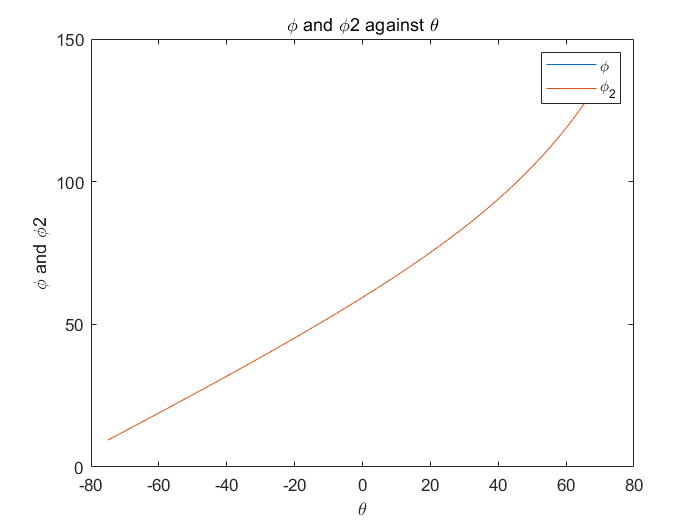

%**********下部**********%
P4.x= -LO_4P4*cos(thetar); P4.y= LO_4P4*sin(thetar); 
P3.x= -LO_3P3*cos(thetar); P3.y= LO_3O_4 + LO_3P3*sin(thetar);
VP3P4=[P4.x-P3.x; P4.y-P3.y]; VO_4P4=[P4.x-O_4.x; P4.y-O_4.y];    %two temporary vector
LP3P4=vecnorm(VP3P4); %and the length of them
phi2= acos(dot(VP3P4, VO_4P4)./(LP3P4*LO_4P4)); %use dot product to calcualte phi2
phi2d= rad2deg(phi2); 
%**********下部**********%
P1.x=O1.x+LO1P1*cos(thetar); P1.y=O1.y+LO1P1*sin(thetar);
P2.x=O2.x+LO2P2*cos(thetar); P2.y=O2.y+LO2P2*sin(thetar);
VP2P1=[P1.x-P2.x; P1.y-P2.y]; VO1P1=[P1.x-O1.x; P1.y-O1.y];
LP1P2= vecnorm(VP2P1);
phi= acos(dot(VP2P1, VO1P1)./(LP1P2*LO1P1));
phid= rad2deg(phi);
%*****plot*****%
plot(thetad, phid, '-'); hold on; %plot phi against theta
plot(thetad, phi2d, '-');hold on; %plot phi2 against theta
title('\phi and \phi2 against \theta')
xlabel('\theta');
ylabel('\phi and \phi2');
legend('\phi', '\phi_2'); 
hold off;

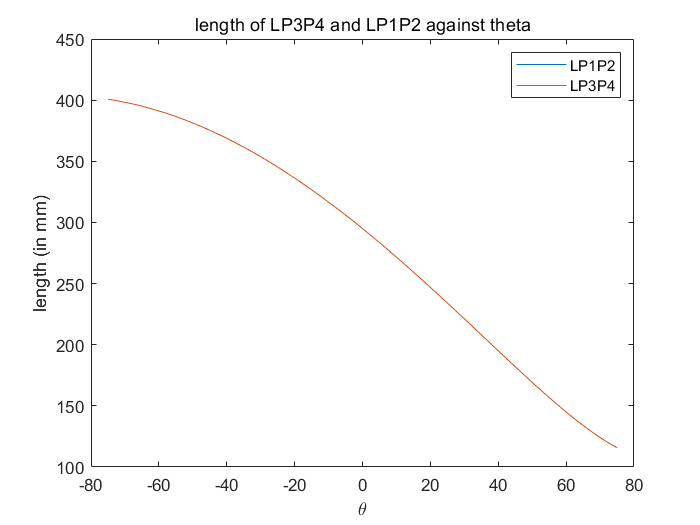


plot(thetad, LP1P2, '-');hold on; %plot phi2 against theta
plot(thetad, LP3P4, '-');hold on; %plot phi2 against theta
title('length of LP3P4 and LP1P2 against theta');
xlabel('\theta');
ylabel('length (in mm)');
legend('LP1P2', 'LP3P4');
hold off

plotting the whole mechanism

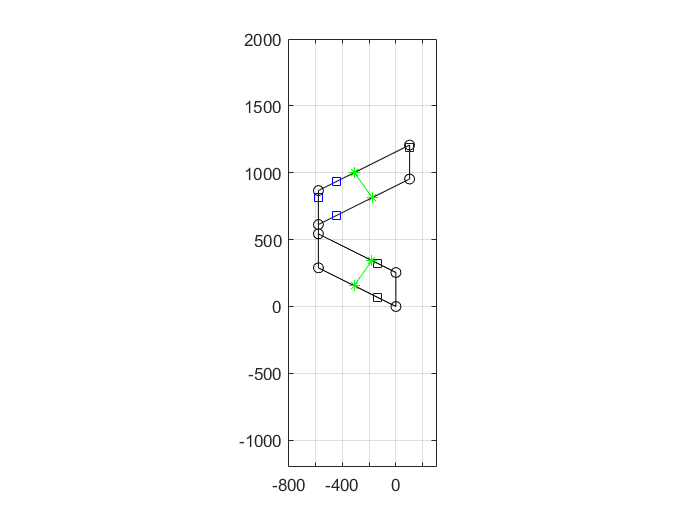

angled=26.5; %angle in degree
ind = find(abs(thetad-angled)<0.001); %find the index of the desired theta(check "find" documentation)

%支點演示
plot([O_4.x(ind) O_3.x(ind)], [O_4.y(ind) O_3.y(ind)], 'o-k'); hold on;
plot([O_4.x(ind) O4.x(ind)], [O_4.y(ind) O4.y(ind)], 'o-k'); hold on;
plot([O_3.x(ind) O3.x(ind)], [O_3.y(ind) O3.y(ind)], 'o-k'); hold on;
plot([O4.x(ind) O3.x(ind)], [O4.y(ind) O3.y(ind)], 'o-k'); hold on;
plot([O3.x(ind) O1.x(ind)], [O3.y(ind) O1.y(ind)], 'o-k'); hold on;
plot([O1.x(ind) O2.x(ind)], [O1.y(ind) O2.y(ind)], 'o-k'); hold on;
plot([O1.x(ind) O_1.x(ind)], [O1.y(ind) O_1.y(ind)], 'o-k'); hold on;
plot([O2.x(ind) O_2.x(ind)], [O2.y(ind) O_2.y(ind)], 'o-k'); hold on;
plot([O_1.x(ind) O_2.x(ind)], [O_1.y(ind) O_2.y(ind)], 'o-k'); hold on;

%質點演示
plot(mO1O_1.x(ind), mO1O_1.y(ind), 'sb'); hold on;
plot(mO2O_2.x(ind), mO2O_2.y(ind), 'sb'); hold on;
plot(mO3O_3.x(ind), mO3O_3.y(ind), 'sb'); hold on;
plot(mO4O_4.x(ind), mO4O_4.y(ind), 'sb'); hold on;
plot(mO_1O_2.x(ind), mO_1O_2.y(ind), 'sb'); hold on;
plot(mO2O4.x(ind), mO2O4.y(ind), 'sb'); hold on;

%彈性材料安裝點演示
plot([P3.x(ind) P4.x(ind)], [P3.y(ind) P4.y(ind)], '*-g'); hold on;
plot([P1.x(ind) P2.x(ind)], [P1.y(ind) P2.y(ind)], '*-g'); hold on;

hold off;
axis([-800 300 -1200 2000]); %set plot size
grid on;
daspect([1 1 1]);

 以下開始求力矩總式


$$\begin{array}{l}
\sum_i f_{1i} \cdot \mathrm{sin}\varphi \cdot {\left(L_{O_{1i} P_{1i} } -L_{O_{2i} P_{2i} } \right)}+\sum_j f_{2j} \cdot sin\varphi_2 \cdot {\left(L_{O_4^{\prime } P_4 } {-L}_{O_3^{\prime } P_3 } \right)}\\
-G_{O_2 O_2^{\prime } } \cdot X_{O_2 O_2^{\prime } } -G_{O_1 O_1^{\prime } } \cdot X_{O_1 O_1^{\prime } } -G_{O_1^{\prime } O_2^{\prime } } \cdot L_{O_1 O_1^{\prime } } \cdot \mathrm{cos}\theta -G_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_3 O_3^{\prime } } -G_{O_4^{\prime } O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_4 O_4^{\prime } } \\
-{\left(G_{O_1^{\prime } O_2^{\prime } } +G_{O_2 O_2^{\prime } } +G_{O_1 O_1^{\prime } } +G_{O_2 O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \right)}\cdot L_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot \mathrm{cos}\theta +M_d =0{\left(40\right)}
\end{array}$$


先求出質心離支點距離

XO1O_1 = mO1O_1.x - O1.x;
XO2O_2 = mO2O_2.x - O2.x;
XO3O_3 = O_3.x - mO3O_3.x;
XO4O_4 = O_4.x - mO4O_4.x;
XO2O4 = O2.x - mO2O4.x;
XO_1O_2 = mO_1O_2.x - O_2.x;

然後求出重力矩部分︰


$$+G_{O_2 O_2^{\prime } } \cdot X_{O_2 O_2^{\prime } } +G_{O_1 O_1^{\prime } } \cdot X_{O_1 O_1^{\prime } } +G_{O_1^{\prime } O_2^{\prime } } \cdot L_{O_1 O_1^{\prime } } \cdot \mathrm{cos}\theta +G_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_3 O_3^{\prime } } +G_{O_4^{\prime } O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot X_{O_4 O_4^{\prime } }$$

$$+{\left(G_{O_1^{\prime } O_2^{\prime } } +G_{O_2 O_2^{\prime } } +G_{O_1 O_1^{\prime } } +G_{O_2 O_4 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \right)}\cdot L_{O_3^{\prime } O_3 \mathrm{\ }\mathrm{\ }\mathrm{\ }} \cdot \mathrm{cos}\theta$$


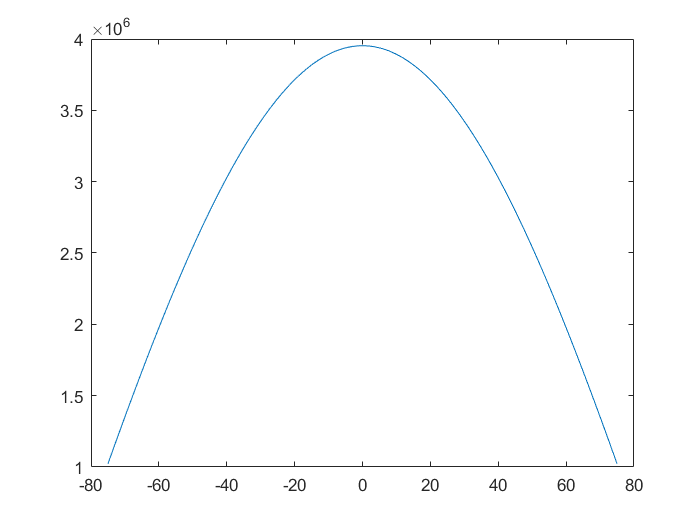

Mg= GO2O_2*XO2O_2 + GO1O_1*XO1O_1 + GO_1O_2*LO1O_1*cos(thetar) + GO3O_3*XO3O_3 + GO4O_4*XO4O_4 ...
+ (GO_1O_2 + GO2O_2 + GO1O_1 +GO2O4)* LO3O_3*cos(thetar);
plot(thetad, Mg);